format shortg
clear all

# Oppgave 1

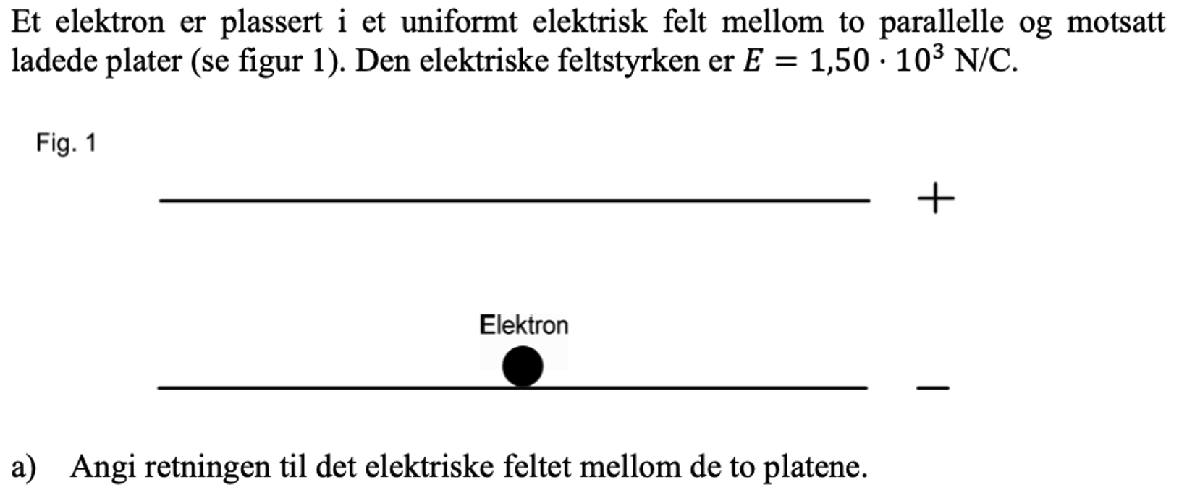

feltet vil gå fra positiv plate til negativ plate, altså nedover

E = 1.50 * 10^3; % N/C


$$F=q*E$$


F = e * E;
a = Newton2(F, m_e, 0);
signif(a, 3)

ans =      2.64e+14


d = 2.00 * 10^-3;
t = signif(KonstantAkselerasjon(d, 0, 0, 0, a), 3)

t =      3.89e-09


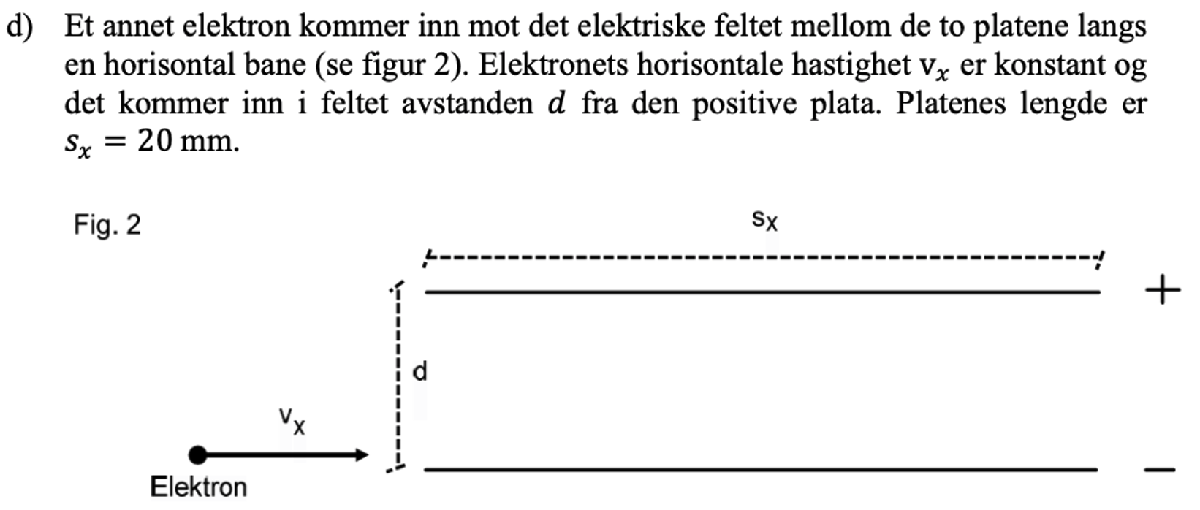

s_x = 20 * 10^-3;

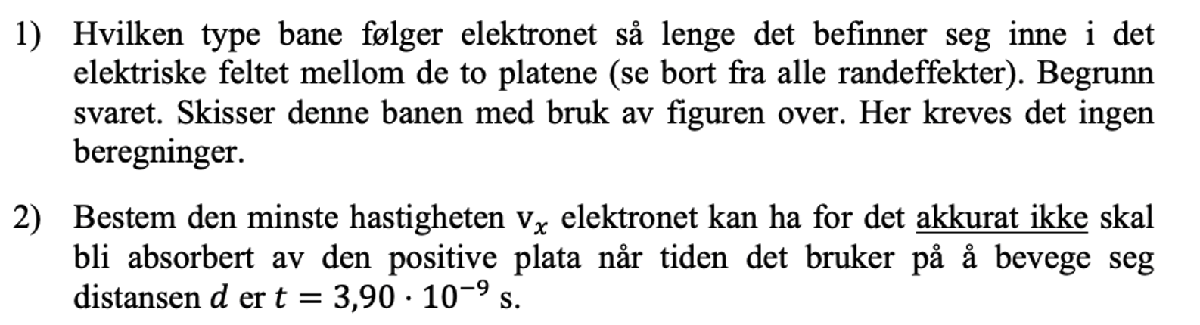

1)

kurve, den vil akselerer oppover (eksponensielt)

2)

v_0 = KonstantFart(s_x, 0, 0, t)

v_0 =    5.1414e+06


# Oppgave 2

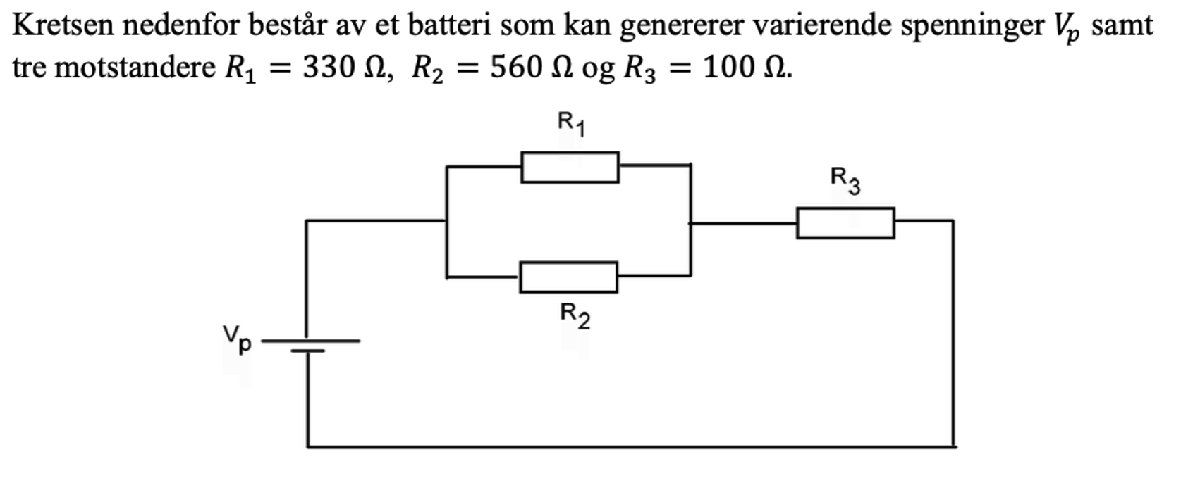

R_1 = 330; % Ohm
R_2 = 560; % Ohm
R_3 = 100; % Ohm

Ut ifra tegningen vil den positivd polen til batteriet pele oppover. Altså vil strømmen gå med klokken.

V_p = 3.00; % Volt

For å finne strømmen ut av batteriet må vi først finne den effektive motstanden til hele kretsen:

R_12 = 1 / ((1/R_1) + (1/R_2));
R_eff = R_12 + R_3

R_eff =        307.64


Deretter finner vi strømmen med Ohms lov:

I = V_p/R_eff;
fprintf('Strømmen I ut av batteriet er: %g Ampere', signif(I, 3))

Strømmen I ut av batteriet er: 0.00975 Ampere

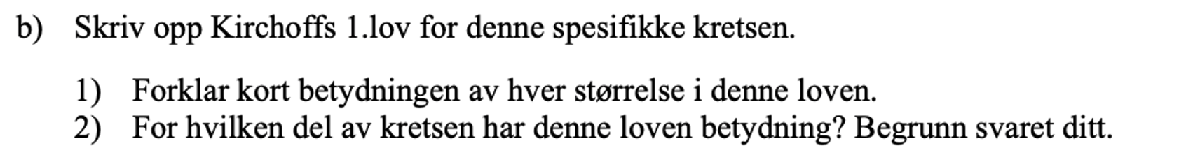

1) Kirchoffs 1. Lov også kalt Kirchoffs forgreiningslov/Junction law sier at summen av strømmer inn og ut av en forgreining vil alltid være 0, eller at summen av strøm inn, er lik summen av strøm ut.

2) I denne kresten kan denne loven kun brukes om strømmen som går inn og ut av parallelkobligen med $R_1 \;\textrm{og}\;R_2$

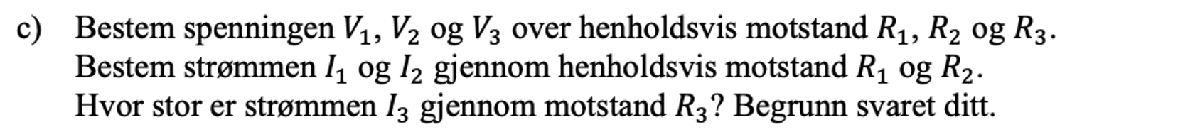

Bruker kirchoffs 1. lov og finner derfor at strømmen gjennom $R_3$må være lik strømmen som kommer ut av batteriet:

I_3 = I;

Bruker kirchofss 2. lov som sier at summen av alle potenislaforskjellene i en lukket krets er lik spenningsfallet over alle komponentene i kretsen. Altså:

V_3 = R_3 * I_3

V_3 =       0.97516


V_12 = V_p - V_3

V_12 =        2.0248


I_1 = V_12/R_1

I_1 =     0.0061359


I_2 = V_12/R_2

I_2 =     0.0036158


fprintf('V_1 = %g Volt\nV_2 = %g Volt\nV_3 = %g Volt\nI_1 = %g Ampere\nI_2 = %g Ampere\nI_3 = %g Ampere', ...
	signif(V_12, 3), signif(V_12, 3), signif(V_3, 3), signif(I_1, 3), signif(I_2, 3), signif(I_3, 3))

V_1 = 2.02 Volt
V_2 = 2.02 Volt
V_3 = 0.975 Volt
I_1 = 0.00614 Ampere
I_2 = 0.00362 Ampere
I_3 = 0.00975 Ampere

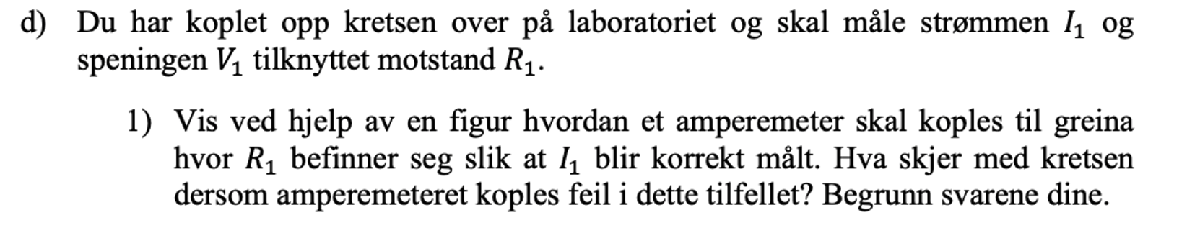

I serie

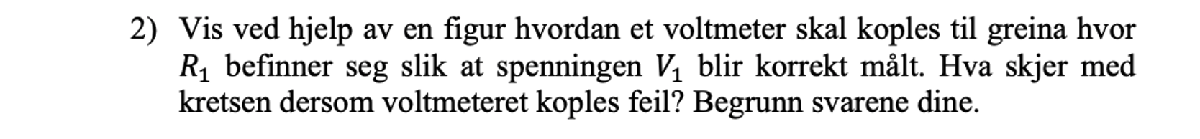

I parallell

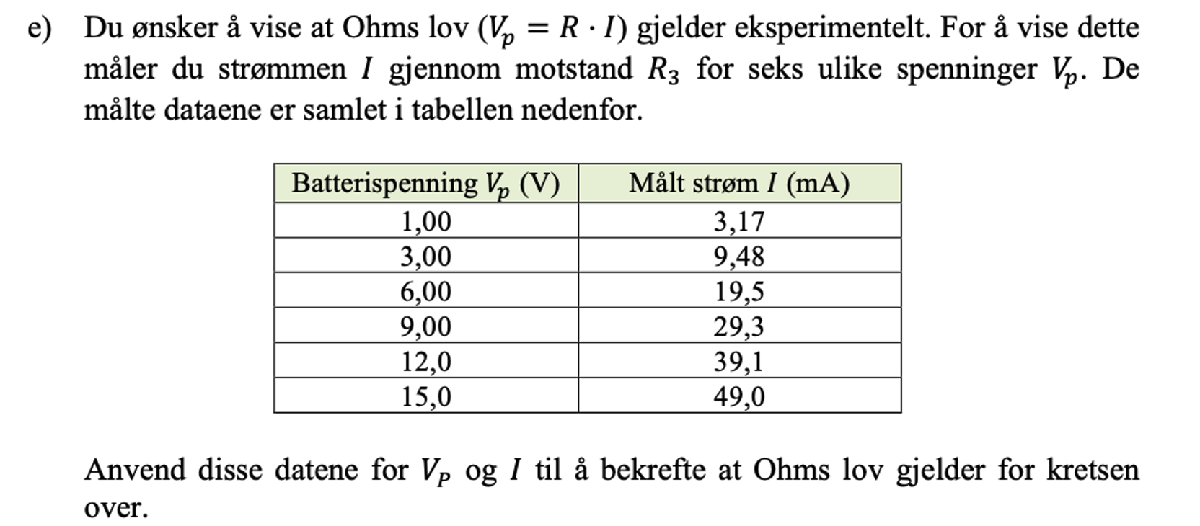

V_p = [1, 3, 6, 9, 12, 15]';
I = signif(V_p / R_eff, 3)

I =       0.00325
      0.00975
       0.0195
       0.0293
        0.039
       0.0488


Som vi ser er gnaske nærme verdiene. Det vi burde gjøre her er å vise at vår beregnede resistans $R_{\textrm{eff}}$ stemmer med disse målte veridene:

I = [3.17, 9.48, 19.5, 29.3, 39.1, 49.0]';
R_eff = zeros(6,1);
for i = 1:6
	R_eff(i,1) = signif(V_p(i,1)/I(i,1), 3);
end
disp(R_eff)

        0.315
        0.316
        0.308
        0.307
        0.307
        0.306



# Oppgave 3

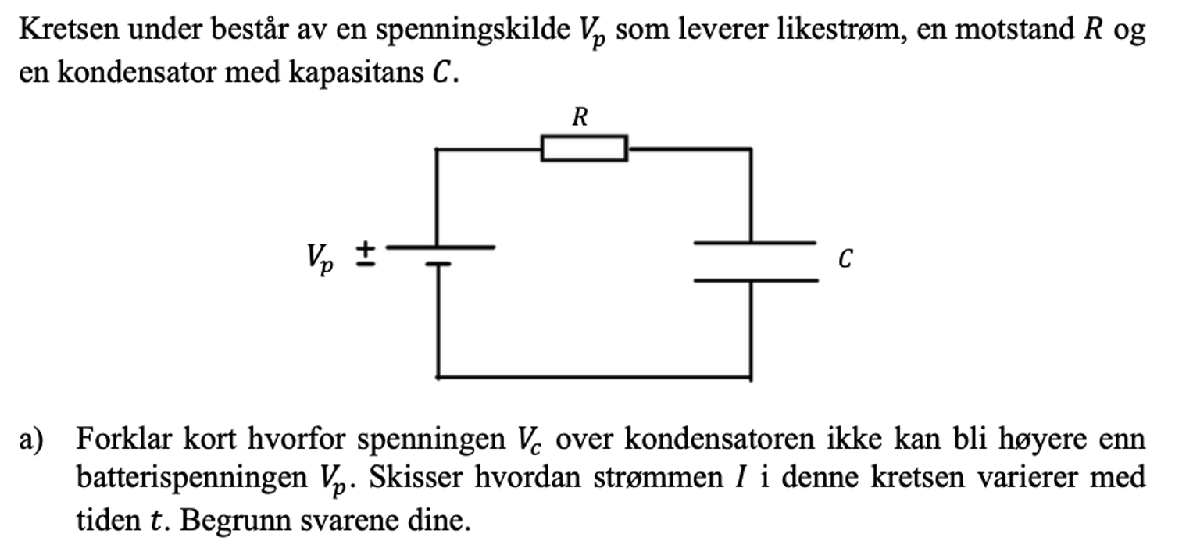

Fordi det er batteriet som bestemmer spenningen,

Strømmen vil starte jævla bra også gradvis dårlige helt til kondensatoren er helt ladet opp og det ikke vil gå strøm lenger.

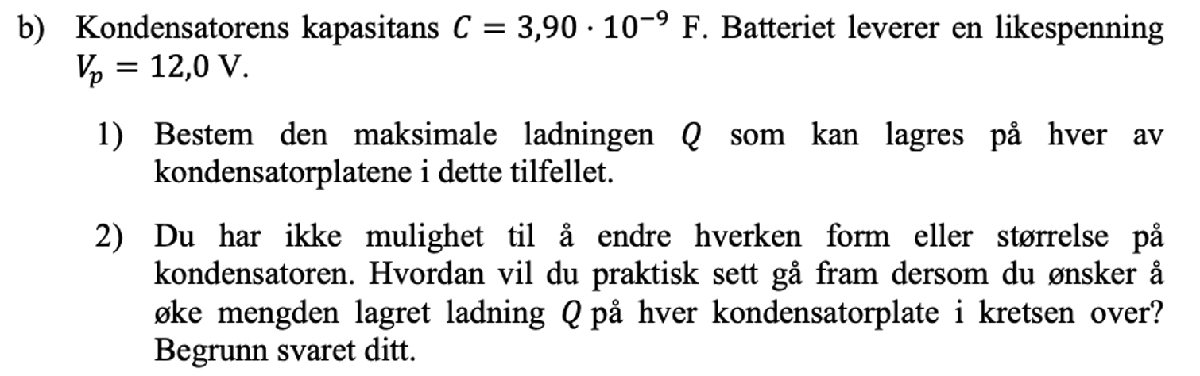

C = 3.90 * 10^-9;
Vp = 12;

1)

Q = C*Vp

Q =      4.68e-08


2)

bruke dielektrikum som er dårligere på å lede strøm, eventuelt øke avstanden mellom platene.

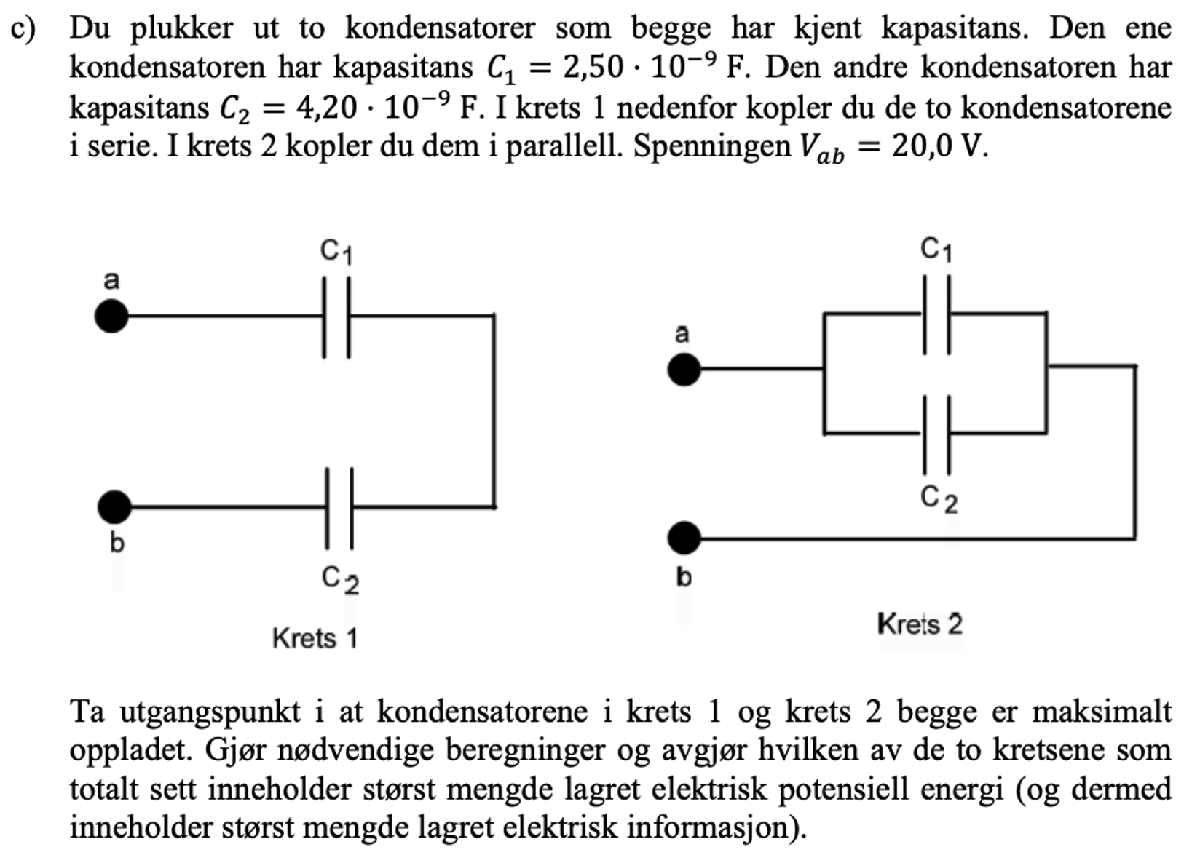

C1 = 2.50 * 10^-9;
C2 = 4.20 * 10^-9;
V = 20;

Arbeidet for å lade opp de to forskjellige koblingene er:

W_par = 1/2 * C_par([C1 C2]) * V^2

W_par =      1.34e-06


W_ser = 1/2 * C_ser([C1 C2]) * V^2

W_ser =    3.1343e-07


Og vi ser at paralellkobling krever mest arbeid for å lade opp, og dermed inneholder også mest elektrisk potenisale/infomrasjon.